# Stability of LTI Systems in State Equations Form: Examples

## Introduction

Given an **LTI system**


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& A\,x(t) + B\,u(t) \\
y(t) &=& C\,x(t) + D\,u(t)
\end{array} \right.$$


in **equilibrium** conditions, i.e.


$$\left\{ \begin{array}{rcl}
u(t) &=& \bar u ,\, \forall t \ge 0 \\
x(0) &=& \bar x
\end{array} \right. \quad \Longrightarrow \quad x(t) = e^{At}x(0) +\int_0^{t} e^{A(t-\tau)}B \bar{u}\,d\tau = \bar x \,,\; \forall t \ge 0$$


Let's **perturbate** the equilibrium state


$$\left\{ \begin{array}{rcl}
u(t) &=& \bar u ,\, \forall t \ge 0 \\
x(0) &=& \bar x + \delta \bar{x}
\end{array} \right. $$


and **analyse** the **perturbed state trajectory**.

## A Marginally Stable Equilibrium State and a Marginally Stable LTI System

Consider the system


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& x_2(t) \\
\dot{x}_2(t) &=& -x_1(t) + u(t) \\
y(t) &=& x_2(t)
\end{array} \right.$$


with the equilibrium


$$u(t) = \bar u,\,\forall t \ge 0 \quad \longrightarrow \quad 
\bar x = \left[\begin{array}{c}
\bar u\\ 0 
\end{array} \right]$$


### The Equilibrium State

clear

A = [0 1; -1 0]; B = [0; 1]; C = [0 1]; D = 0; % the LTI state equation matrices
sysEX1 = ss(A, B, C, D); % the LTI system

barU = 4.5; % select the input value at the equilibrium
barX = linsolve(A, -B * barU);     % the corresponding equilibrium state

x0 = barX; % the initial state


% final simulation time instant
Tstop = 30;

t = (0: 1e-3:Tstop); % a set of simulation time-steps

### The Nominal Trajectory

% the free nominal traj.
[~, ~, x_free] = initial(sysEX1, barX, t);
% the forced nominal traj.
u = barU*ones(size(t));
[~, ~, x_forced] = lsim(sysEX1, u, t);

nominalX = x_free + x_forced;


### The Perturbation on the Initial State

deltaX = 0.283; % Set the state perturbation MAX magnitude

perturbedX0 = x0 + deltaX*(2*rand(size(x0))-1);

### The Perturbed Trajectory

% the free perturbed traj.
[~, ~, x_freeP] = initial(sysEX1, perturbedX0, t);
% the forced perturbed traj.
u = barU*ones(size(t));
[~, ~, x_forcedP] = lsim(sysEX1, u, t);

perturbedX = x_freeP + x_forcedP;

### Analyse the Result

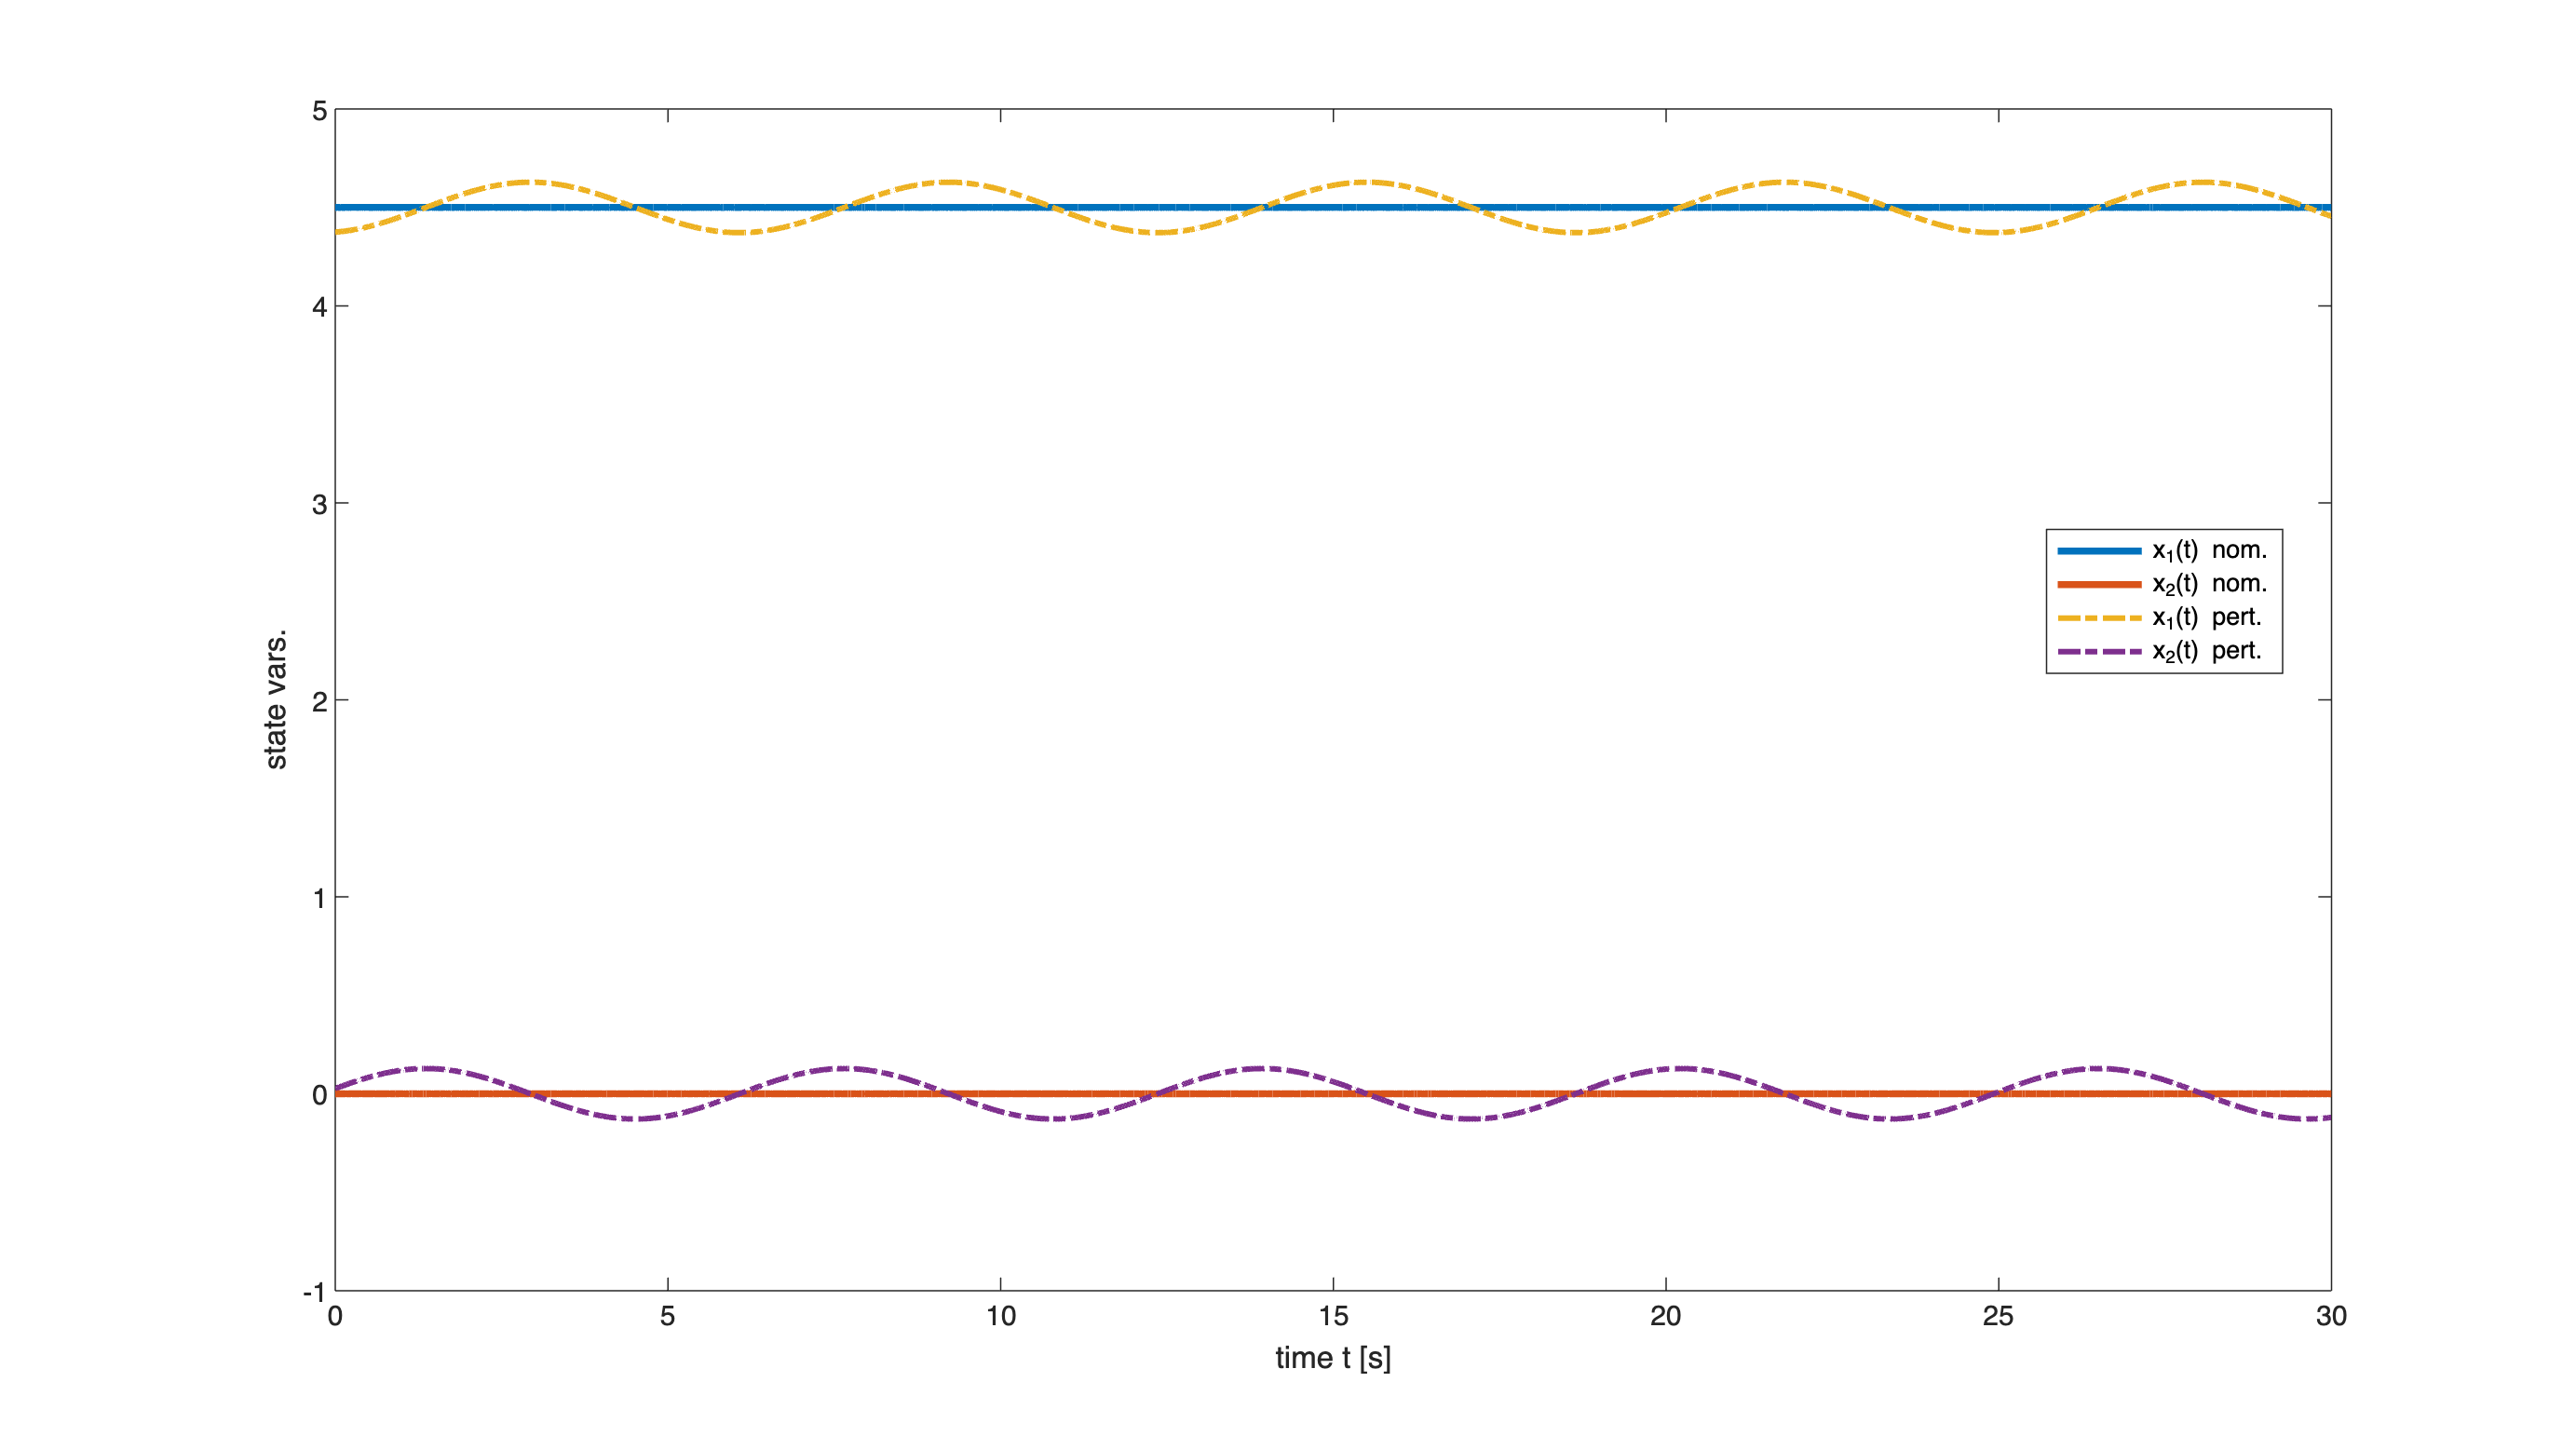

figure('Units','normalized', 'Position',[0.1, 0.1, 0.95, 0.95]);
plot(t, nominalX, 'LineStyle','-', 'LineWidth', 2.5);
hold on;
plot(t, perturbedX, 'LineStyle','-.', 'LineWidth', 2.0);
xlabel('time t [s]');
ylabel('state vars.');
legend('x_{1}(t) nom.', 'x_{2}(t) nom.', 'x_{1}(t) pert.', 'x_{2}(t) pert.', ...
    'Location', 'best');

**Remark**: the perturbed state trajectory starts **near** the equilibrium state $\bar x$ and **remains near** the nominal equilibrium trajectory.

Note: the eigenvalues of the matrix A are complex numbers (pure imaginary complex numbers)

eig(A)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i


## An Asymptotically Stable Equilibrium State and an Asymptotically Stable LTI System

Consider the system


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& x_2(t) \\
\dot{x}_2(t) &=& -x_1(t) -x_2(t)+ u(t) \\
y(t) &=& x_2(t)
\end{array} \right.$$


with the equilibrium


$$u(t) = \bar u,\,\forall t \ge 0 \quad \longrightarrow \quad 
\bar x = \left[\begin{array}{c}
\bar u\\ 0 
\end{array} \right]$$


### The Equilibrium State

clear

A = [0 1; -1 -1]; B = [0; 1]; C = [0 1]; D = 0; % the LTI state equation matrices
sysEX2 = ss(A, B, C, D); % the LTI system

barU = 4.5; % select the input value at the equilibrium
barX = linsolve(A, -B * barU);     % the corresponding equilibrium state

x0 = barX; % the initial state


% final simulation time instant
Tstop = 30;

t = (0: 1e-3:Tstop); % a set of simulation time-steps

### The Nominal Trajectory

% the free nominal traj.
[~, ~, x_free] = initial(sysEX2, barX, t);
% the forced nominal traj.
u = barU*ones(size(t));
[~, ~, x_forced] = lsim(sysEX2, u, t);

nominalX = x_free + x_forced;


### The Perturbation on the Initial State

deltaX = -2; % Set the state perturbation MAX magnitude

perturbedX0 = x0 + deltaX*(2*rand(size(x0))-1);

### The Perturbed Trajectory

% the free perturbed traj.
[~, ~, x_freeP] = initial(sysEX2, perturbedX0, t);
% the forced perturbed traj.
u = barU*ones(size(t));
[~, ~, x_forcedP] = lsim(sysEX2, u, t);

perturbedX = x_freeP + x_forcedP;

### Analyse the Result

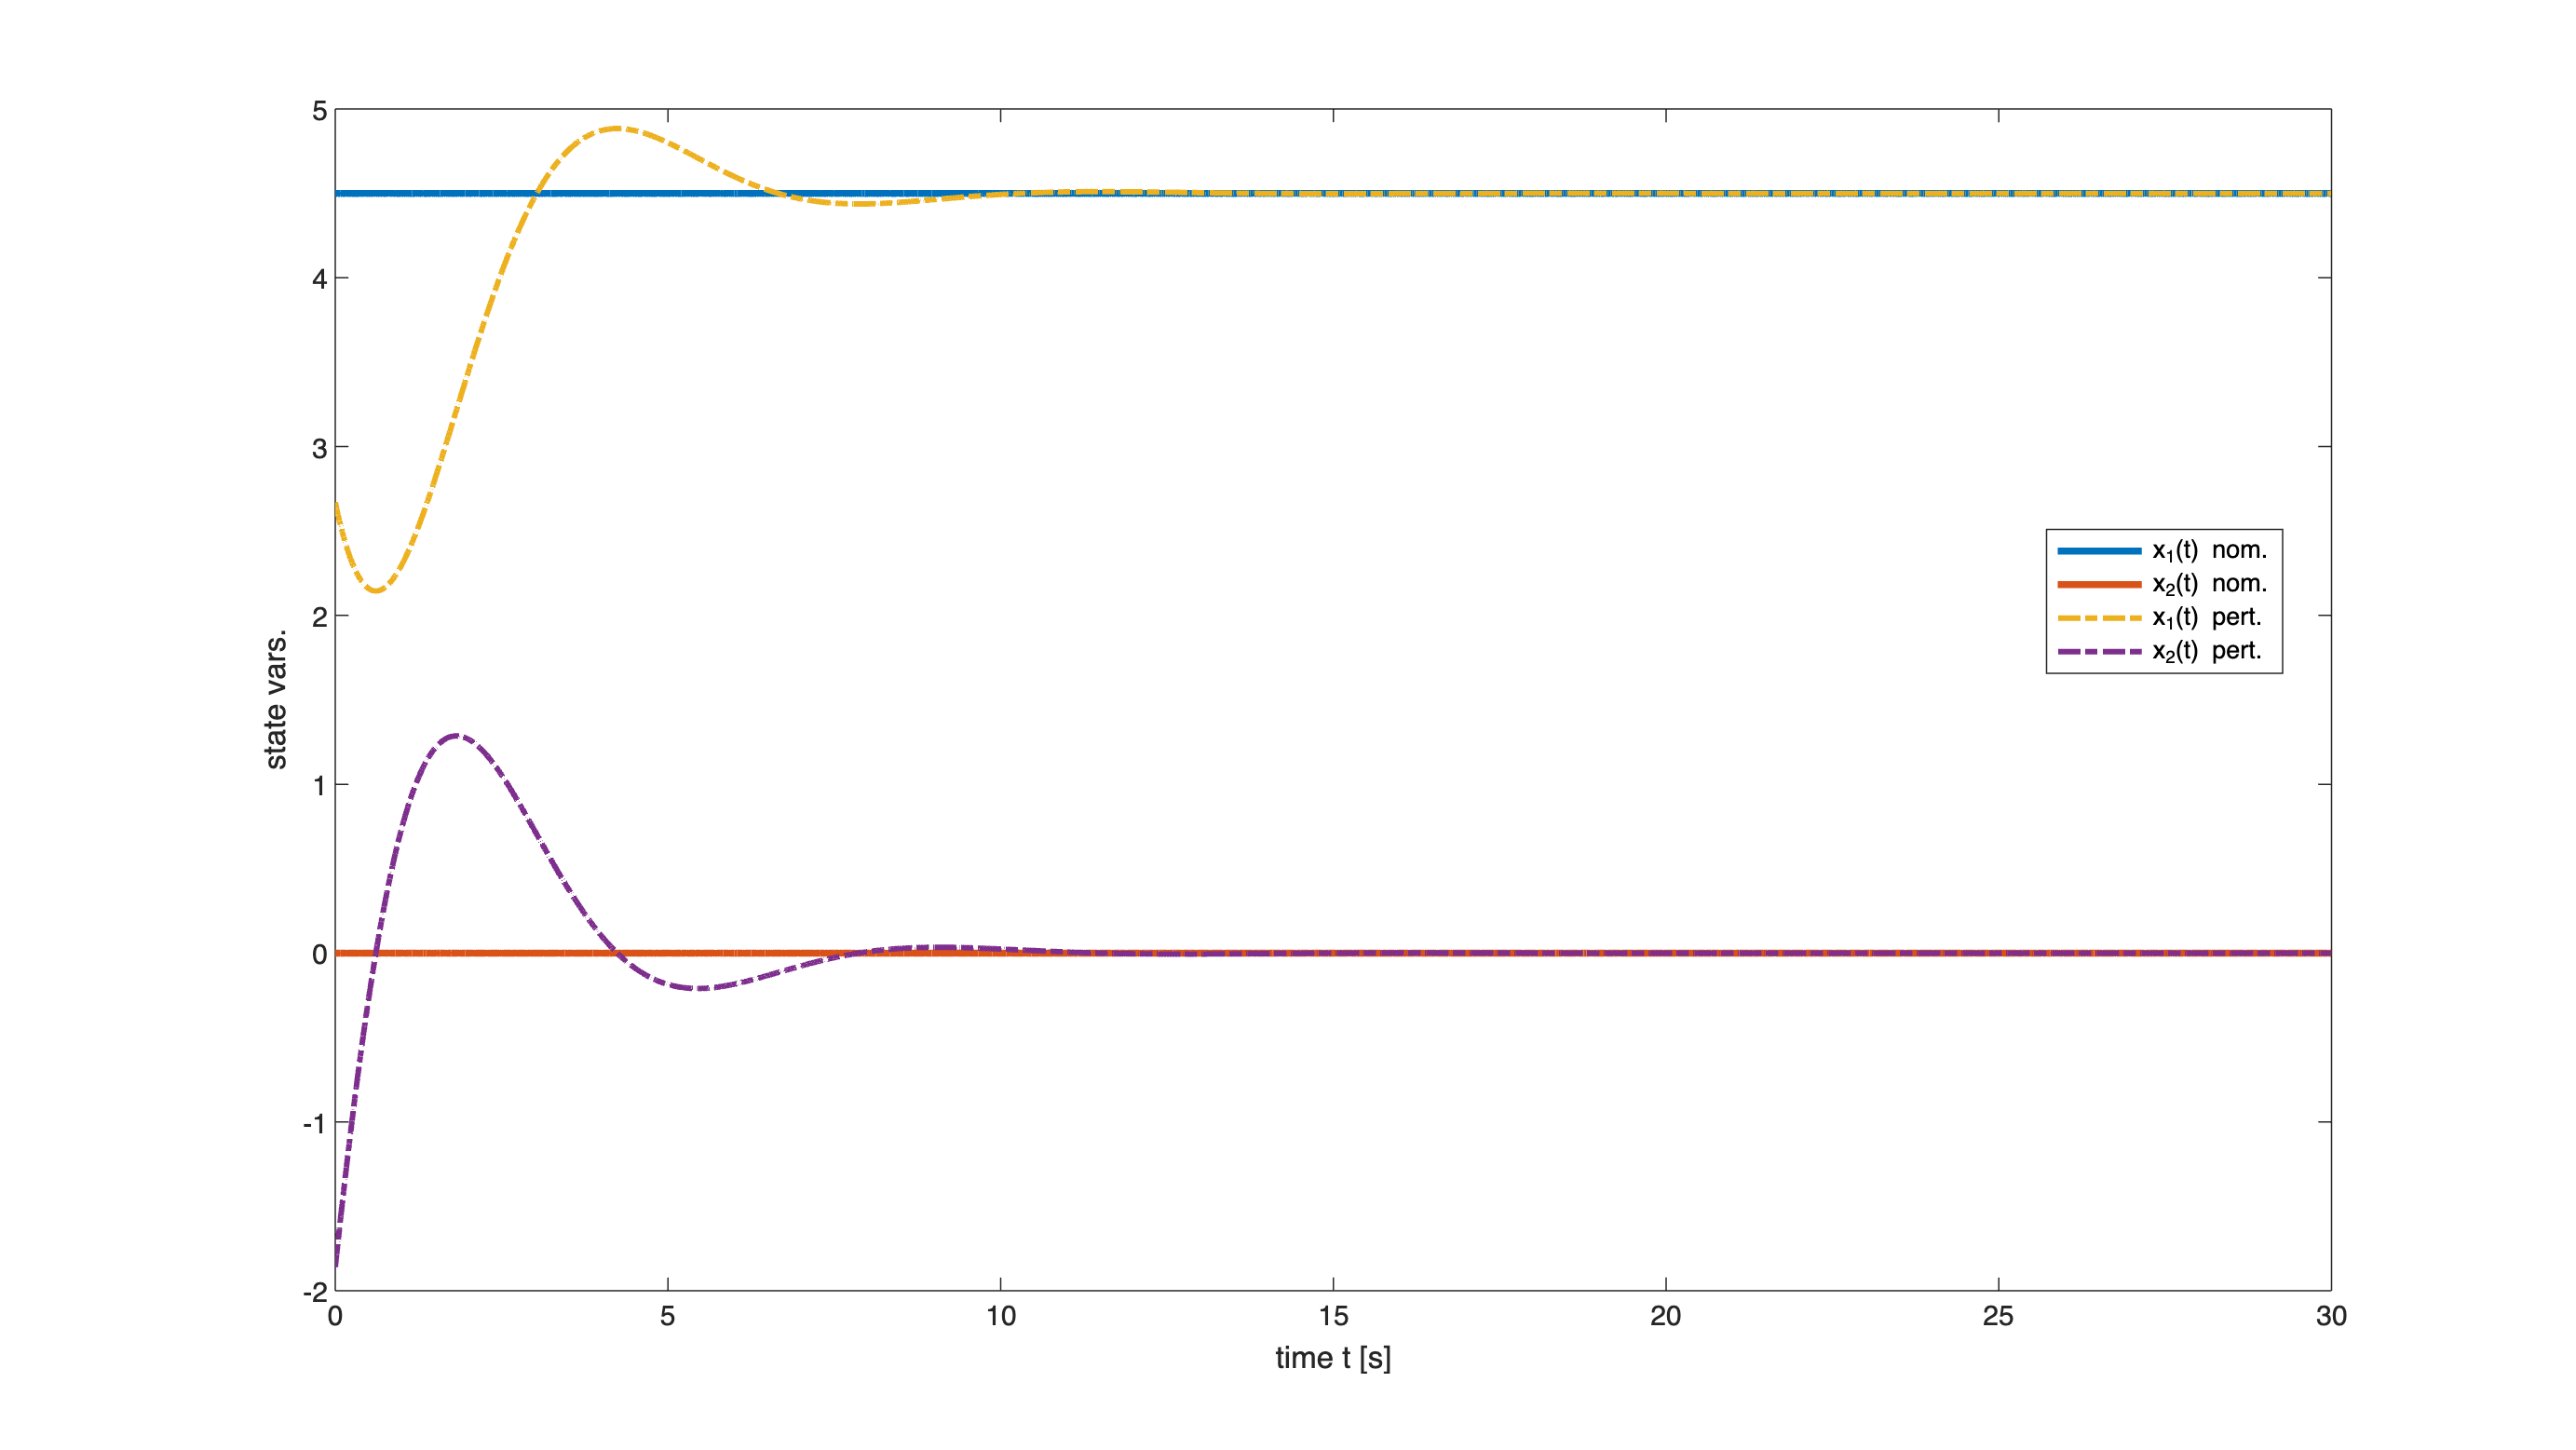

figure('Units','normalized', 'Position',[0.1, 0.1, 0.95, 0.95]);
plot(t, nominalX, 'LineStyle','-', 'LineWidth', 2.5);
hold on;
plot(t, perturbedX, 'LineStyle','-.', 'LineWidth', 2);
xlabel('time t [s]');
ylabel('state vars.');
legend('x_{1}(t) nom.', 'x_{2}(t) nom.', 'x_{1}(t) pert.', 'x_{2}(t) pert.', ...
    'Location', 'best');

**Remark**: the **perturbed** **state** trajectory starts **near** the equilibrium state $\bar x$ and **returns** (in infinite time) to the **nominal equilibrium** trajectory.

If the eigenvalues of the matrix A are determined:

eig(A)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


## An Unstable Equilibrium State and an Unstable LTI System

Consider the system


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& 2 x_1(t) - x_2(t) \\
\dot{x}_2(t) &=& -x_1(t) +2x_2(t)+ u(t) \\
y(t) &=& x_2(t)
\end{array} \right.$$


with the equilibrium


$$u(t) = \bar u,\,\forall t \ge 0 \quad \longrightarrow \quad 
\bar x = \left[\begin{array}{c}
\frac{\bar u}{3}\\  \frac{2\,\bar u}{3}
\end{array} \right]$$


### The Equilibrium State

clear

A = [2 -1; -1 +2]; B = [0; 1]; C = [0 1]; D = 0; % the LTI state equation matrices
sysEX3 = ss(A, B, C, D); % the LTI system

barU = 3; % select the input value at the equilibrium
barX = linsolve(A, -B * barU);     % the corresponding equilibrium state

x0 = barX; % the initial state


% final simulation time instant
Tstop = 5;

t = (0: 1e-3:Tstop); % a set of simulation time-steps

### The Nominal Trajectory

% the free nominal traj.
[~, ~, x_free] = initial(sysEX3, barX, t);
% the forced nominal traj.
u = barU*ones(size(t));
[~, ~, x_forced] = lsim(sysEX3, u, t);

nominalX = x_free + x_forced;


### The Perturbation on the Initial State

deltaX = 0.019; % Set the state perturbation MAX magnitude

perturbedX0 = x0 + deltaX*(2*rand(size(x0))-1);

### The Perturbed Trajectory

% the free perturbed traj.
[~, ~, x_freeP] = initial(sysEX3, perturbedX0, t);
% the forced perturbed traj.
u = barU*ones(size(t));
[~, ~, x_forcedP] = lsim(sysEX3, u, t);

perturbedX = x_freeP + x_forcedP;

### Analyse the Result

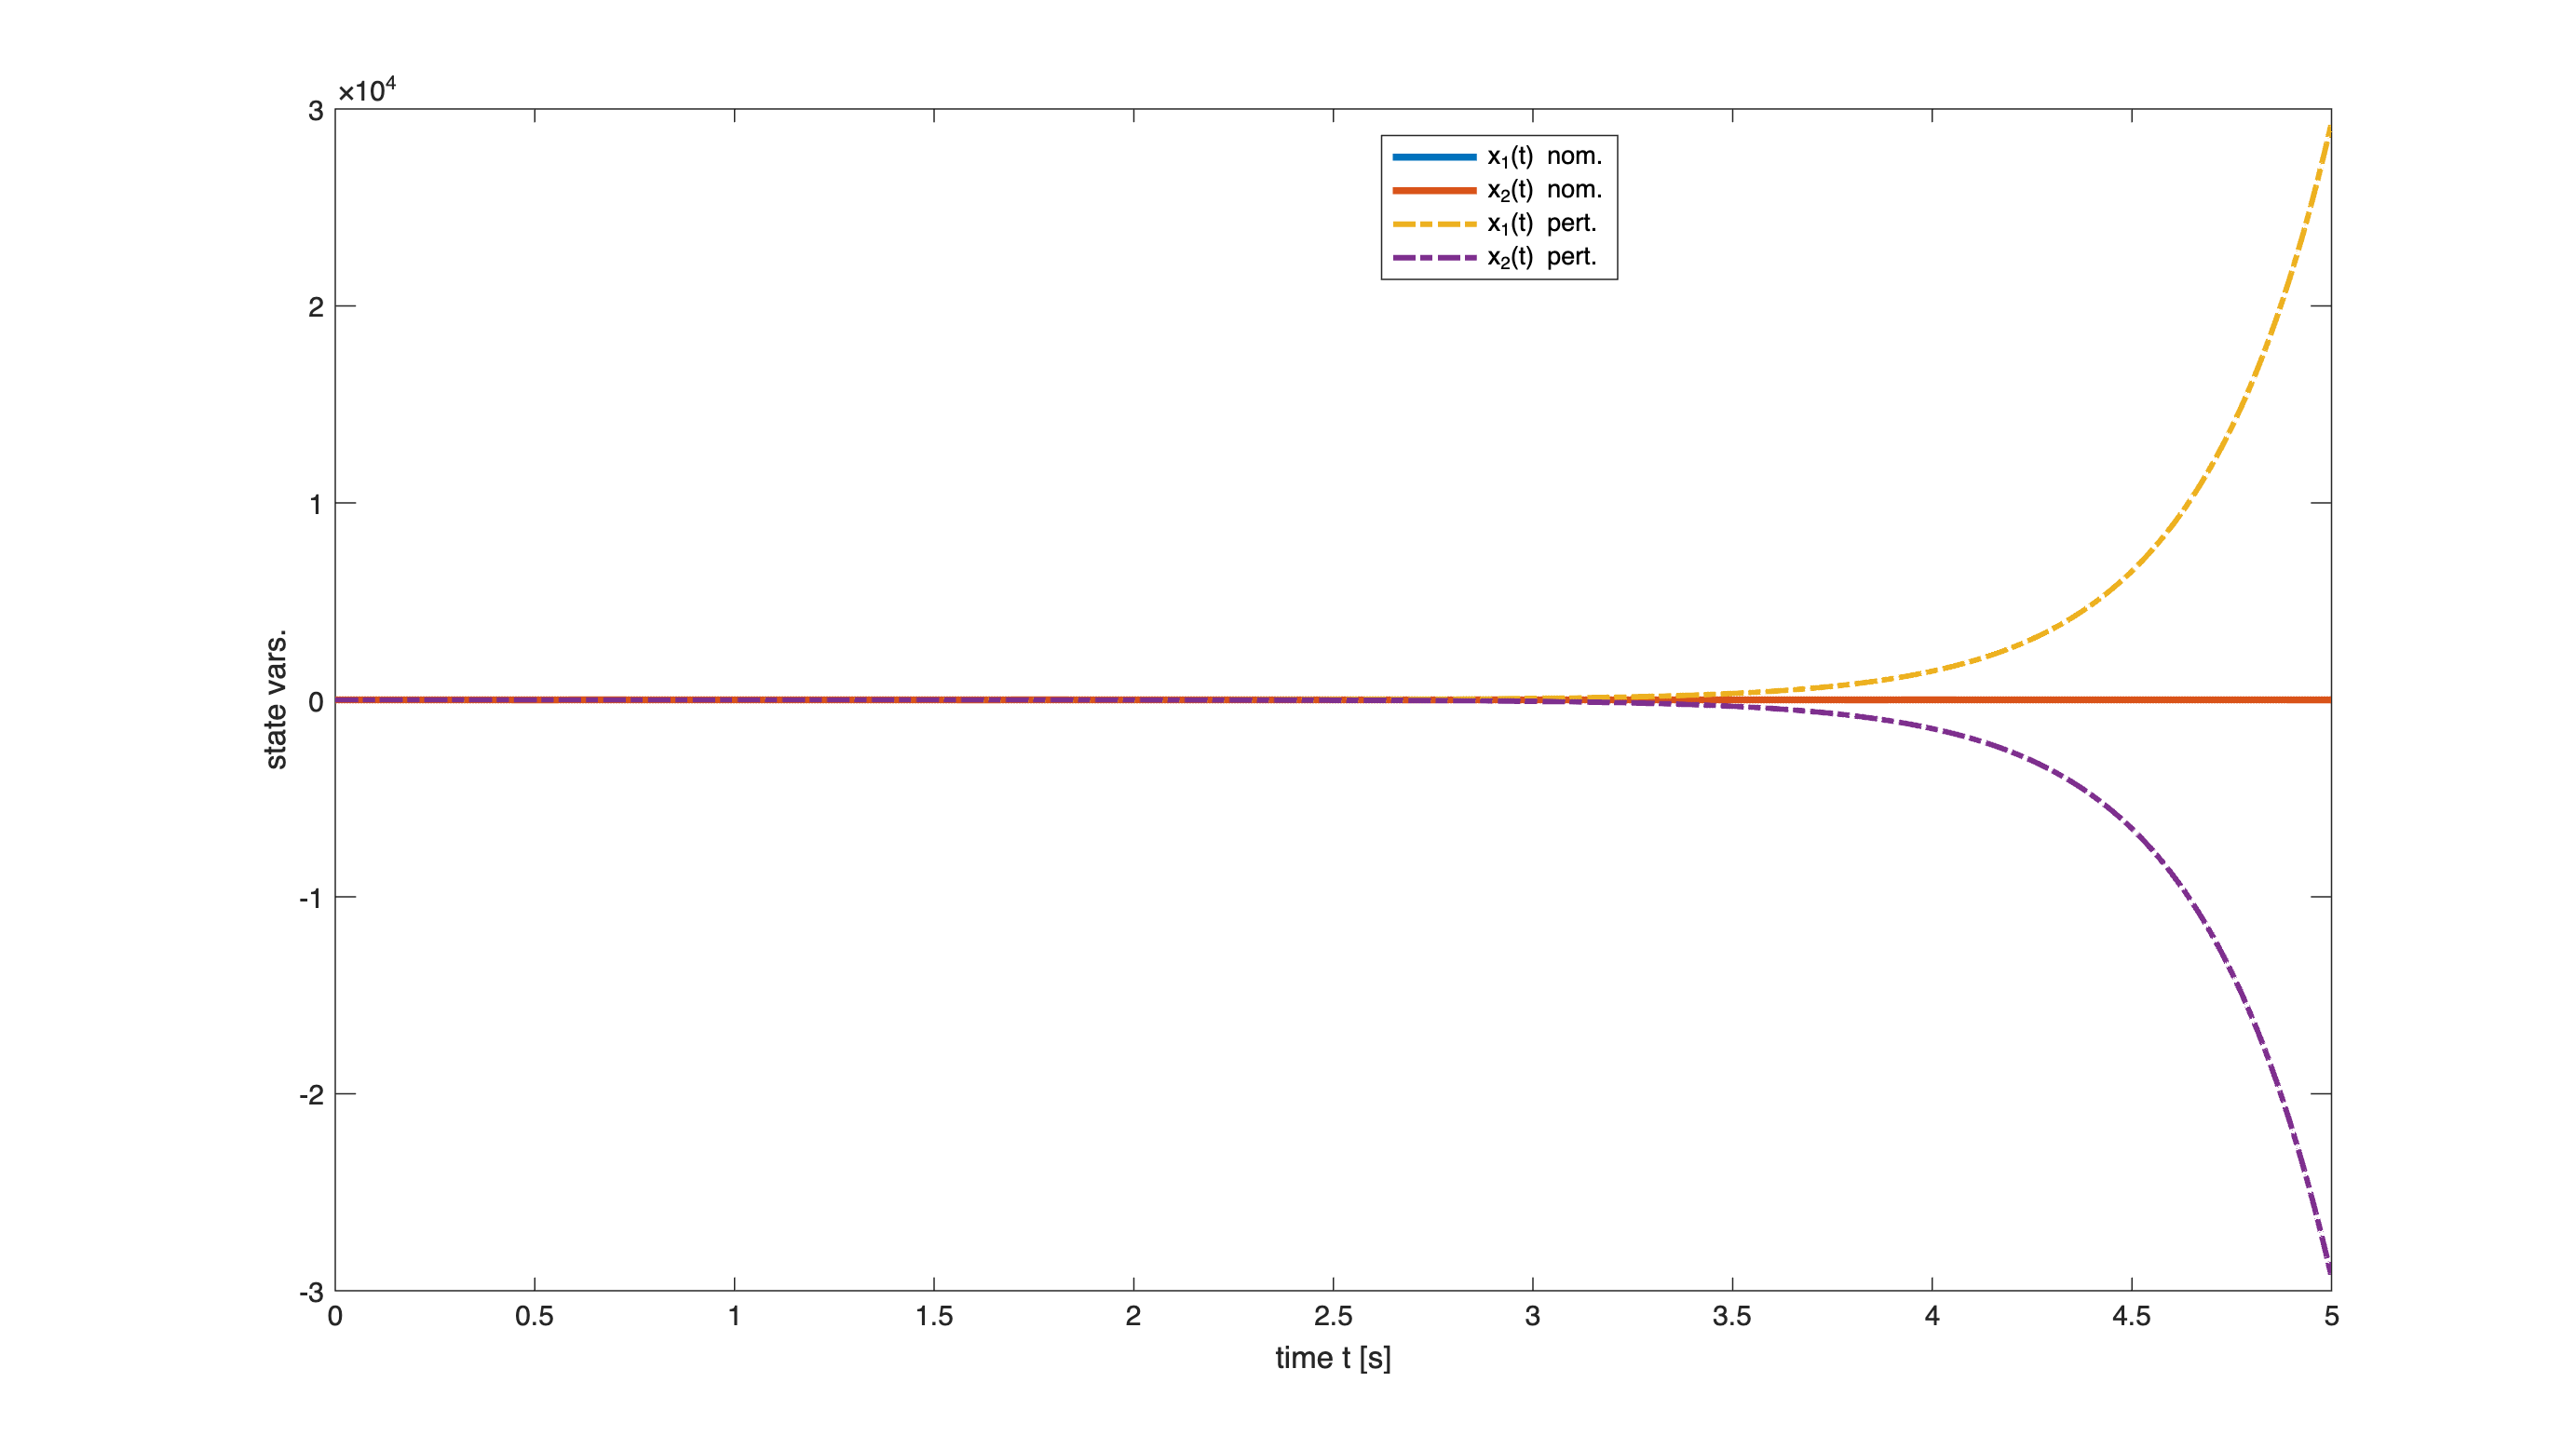

figure('Units','normalized', 'Position',[0.1, 0.1, 0.95, 0.95]);
plot(t, nominalX, 'LineStyle','-', 'LineWidth', 2.5);
hold on;
plot(t, perturbedX, 'LineStyle','-.', 'LineWidth', 2);
xlabel('time t [s]');
ylabel('state vars.');
legend('x_{1}(t) nom.', 'x_{2}(t) nom.', 'x_{1}(t) pert.', 'x_{2}(t) pert.', ...
    'Location', 'best');

**Remark**: the trajectory of the **perturbed** **state** starts **near** the equilibrium state $\bar x$ but **moves further and further away** from the nominal equilibrium trajectory.

If the eigenvalues of the matrix A are determined:

eig(A)

ans =      1
     3
